clc
clear

## Settings

read_data = false;
load_models = false;
train_LDA = true;
make_LDA_pred = false;
save_models = false;
plot_conf = true;
new_pred = true;

## Read data

if (read_data)
% Full testing set
FullSet = readtable("results\Data\testing_measured_data_combined.csv");

A.features = [FullSet.c_LO_measured FullSet.c_RE_measured FullSet.f_PLSP_measured...
                FullSet.f_PLSS_measured FullSet.f_LO_measured FullSet.f_LE_measured... 
                FullSet.c_PLS_measured FullSet.c_LE_measured FullSet.c_RaffP_measured...
                FullSet.c_RaffS_measured FullSet.c_BO_measured]

A = struct with fields:
    features: [2073608×11 double]



X = A.features;
y = FullSet.state_code;

% Training set
TrainingSet = readtable("results\Data\training_measured_data_combined.csv");

B = table();
B.c_LO_measured = TrainingSet.c_LO_measured;
B.c_RE_measured = TrainingSet.c_RE_measured;
B.f_PLSP_measured = TrainingSet.f_PLSP_measured;
B.f_PLSS_measured = TrainingSet.f_PLSS_measured;
B.f_LO_measured = TrainingSet.f_LO_measured;
B.f_LE_measured = TrainingSet.f_LE_measured;
B.c_PLS_measured = TrainingSet.c_PLS_measured;
B.c_LE_measured = TrainingSet.c_LE_measured;
B.c_RaffP_measured = TrainingSet.c_RaffP_measured;
B.c_RaffS_measured = TrainingSet.c_RaffS_measured;
B.c_BO_measured = TrainingSet.c_BO_measured;

% Testing set - only single faults
SeparateSet = readtable("results\Data\testing_separate_measured_data_combined.csv");

C.features = [SeparateSet.c_LO_measured SeparateSet.c_RE_measured SeparateSet.f_PLSP_measured...
                SeparateSet.f_PLSS_measured SeparateSet.f_LO_measured SeparateSet.f_LE_measured... 
                SeparateSet.c_PLS_measured SeparateSet.c_LE_measured SeparateSet.c_RaffP_measured...
                SeparateSet.c_RaffS_measured SeparateSet.c_BO_measured]

C = struct with fields:
    features: [1296005×11 double]
           y: {1296005×1 cell}


C.y = SeparateSet.state_code;
end

## Load models

if (load_models)
load('results\Models\gaussian_SVM_model.mat');
% 
% load('results\Models\kNN_2comp_model.mat');
% kNN_2comp_model = kNN_final;
% 
% load('results\Models\kNN_4comp_model.mat');
% kNN_4comp_model = kNN_final;

load('results\Models\kNN_model.mat');
kNN_model = final_kNN_model;
% 
% load('results\Models\LDA_2comp_model.mat');
% LDA_2comp_model = lda_final;
% 
% load('results\Models\LDA_4comp_model.mat');
% LDA_4comp_model = lda_final;
end

## Make predictions


X_N = normalize(X);
B_N = normalize(B);
y_B = TrainingSet.state_code;

if (train_LDA)
% Apply LDA for dimensionality reduction 2 components
LDA2.num_components = 2;
lda_model = fitcdiscr(B_N, y_B); % Fit the LDA model
[LDA2.eigenvectors, LDA2.eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, LDA2.sorted_indices] = sort(diag(LDA2.eigenvalues), 'descend');
LDA2.projection_matrix = LDA2.eigenvectors(:, LDA2.sorted_indices(1:LDA2.num_components));

% Project training and testing data onto the LDA components
LDA2.B_reduced = B_N * LDA2.projection_matrix;
LDA2.X_reduced = X_N * LDA2.projection_matrix;
kNN_2comp_model = fitcknn(LDA2.B_reduced, y, 'NumNeighbors', 90);
LDA_2comp_model = fitcdiscr(LDA2.B_reduced, y);

% Apply LDA for dimensionality reduction 2 components
LDA4.num_components = 4;
[LDA4.eigenvectors, LDA4.eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, LDA4.sorted_indices] = sort(diag(LDA4.eigenvalues), 'descend');
LDA4.projection_matrix = LDA4.eigenvectors(:, LDA4.sorted_indices(1:LDA4.num_components));

% Project training and testing data onto the LDA components
LDA4.B_reduced = B_N * LDA4.projection_matrix;
LDA4.X_reduced = X_N * LDA4.projection_matrix;
kNN_4comp_model = fitcknn(LDA4.B_reduced, y, 'NumNeighbors', 9);
LDA_4comp_model = fitcdiscr(LDA4.B_reduced, y);
end


if (make_LDA_pred)
[LDA2.y_pred, LDA2.scores, LDA2.cost] = predict(LDA_2comp_model, LDA2.X_reduced);

[LDA4.y_pred, LDA4.scores, LDA4.cost] = predict(LDA_4comp_model, LDA4.X_reduced);

[kNN2.y_pred, kNN2.scores, kNN2.cost] = predict(kNN_2comp_model, LDA2.X_reduced);

[kNN4.y_pred, kNN4.scores, kNN4.cost] = predict(kNN_4comp_model, LDA4.X_reduced);
end

% kNN Only
% [kNN.y_pred, kNN.scores, kNN.cost] = predict(kNN_model, X);

% Gaussian SVM
% [SVM_G.y_pred, SVM_G.scores] = gaussian_SVM_model.predictFcn(X);

sum(kNN4.scores,1)

ans = 	1.0e+05 *

    4.5602    3.1050    0.0151    9.1400    3.8743    0.0233    0.0181


if (plot_conf)
LDA2.mat = confusionmat(y, LDA2.y_pred);
disp('LDA 2 Comp Confusion Matrix:');

LDA 2 Comp Confusion Matrix:


disp(LDA2.mat);

      909893          60           0         242           0           2         162
      419627       36162           0           0           0         164           0
        1920           1           0           0           0           0           0
      155001           0           0      188958           0       43758           0
        2719           0           0           0           0           0           0
      133777       23925           0           0           0      153556           0
          13           0           0           0           0        1523           0



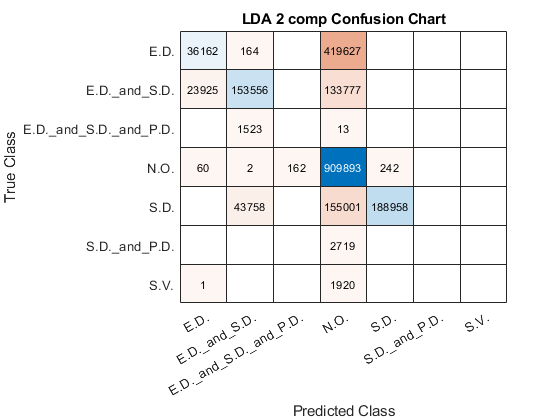

confusionchart(y, LDA2.y_pred)
title('LDA 2 comp Confusion Chart');


LDA4.mat = confusionmat(y, LDA4.y_pred);
disp('LDA 4 Comp Confusion Matrix:');

LDA 4 Comp Confusion Matrix:


disp(LDA4.mat);

      909991          31           0         268           0           1          68
      299727       64299           0          40           0       91887           0
        1920           1           0           0           0           0           0
      201834           0           0      185883           0           0           0
        2719           0           0           0           0           0           0
       36110       45262           0           0           0      229354         532
           0           0           0           0           0        1536           0



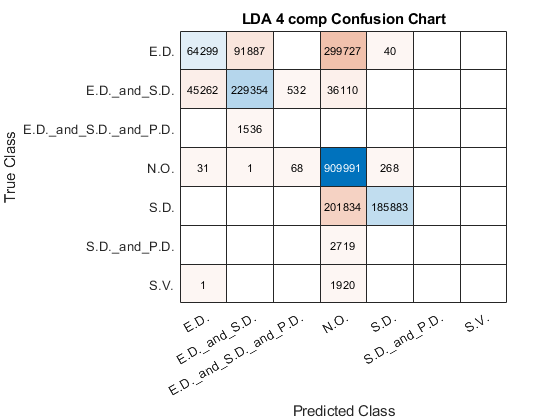

confusionchart(y, LDA4.y_pred)
title('LDA 4 comp Confusion Chart');


kNN2.mat = confusionmat(y, kNN2.y_pred);
disp('kNN 2 Comp Confusion Matrix:');

kNN 2 Comp Confusion Matrix:


disp(kNN2.mat);

      875461       31388           2        3029           0         479           0
      167274      256776          28       14640           0       17235           0
         725         636         481          79           0           0           0
       12135        6666           0      355489           0       13427           0
        2599         120           0           0           0           0           0
        1564       23545           0       37022           0      249053          74
           0           0           0           0           0        1449          87



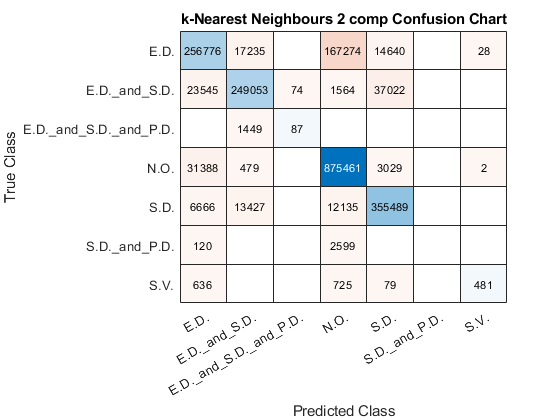

confusionchart(y, kNN2.y_pred)
title('k-Nearest Neighbours 2 comp Confusion Chart');


kNN4.mat = confusionmat(y, kNN4.y_pred);
disp('kNN 4 Comp Confusion Matrix:');

kNN 4 Comp Confusion Matrix:


disp(kNN4.mat);

      885356       23835          15        1073           3          77           0
       94299      351240           3          75           0       10336           0
         800          15        1098           7           0           1           0
        7539         751           6      379404           0          17           0
        2582         137           0           0           0           0           0
        1007        5497           0          20           0      304621         113
           0           0           0           0           0         222        1314



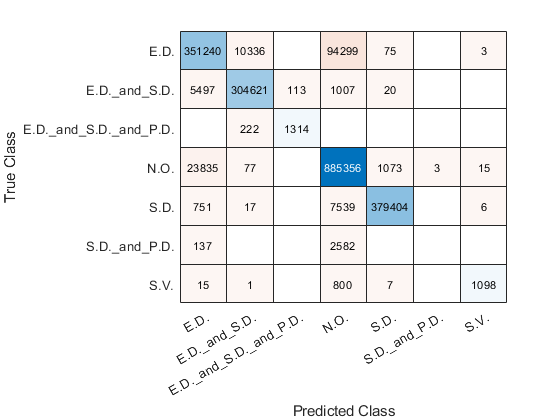

confusionchart(y, kNN4.y_pred)

title('k-Nearest Neighbours 4 comp Confusion Chart');

kNN.mat = confusionmat(y, kNN.y_pred);
disp('kNN Confusion Matrix:');

kNN Confusion Matrix:


disp(kNN.mat);

      876445       33800          67          47           0           0           0
      430972       24981           0           0           0           0           0
        1920           1           0           0           0           0           0
      377998        9719           0           0           0           0           0
        2719           0           0           0           0           0           0
      222050       89208           0           0           0           0           0
        1535           1           0           0           0           0           0



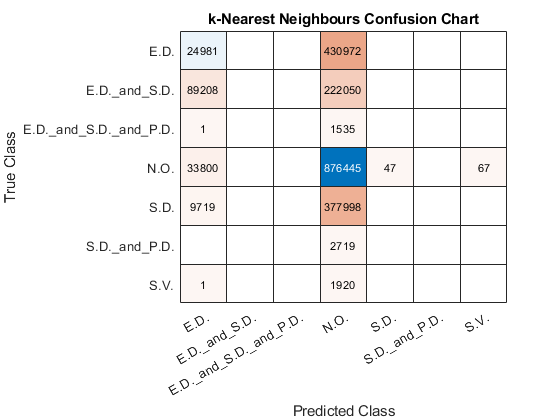

confusionchart(y, kNN.y_pred)
title('k-Nearest Neighbours Confusion Chart');


SVM_G.mat = confusionmat(y, SVM_G.y_pred);
disp('SVM Gaussian Confusion Matrix:');

SVM Gaussian Confusion Matrix:


disp(SVM_G.mat);

      822181       79292         200        4130           0           0           0        4556
      148987      305173         184         789           0           0           0         820
        1309         174         438           0           0           0           0           0
      237139        5707           0      144838           0           0           0          33
        2450         246           1           4           0           0           0          18
      214571       83221           0       13440           0           0           0          26
        1536           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0



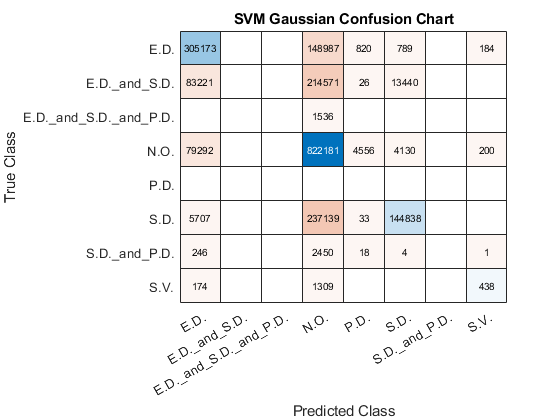

confusionchart(y, SVM_G.y_pred)
title('SVM Gaussian Confusion Chart');

end

if (new_pred)
    kNN.new_scores = [kNN.scores(:, 1) kNN.scores(:,3:end)];
    SVM_G.new_scores = [SVM_G.scores(:,1) SVM_G.scores(:,3:end)];
end

threshold = 0.2; 
SVM_G.new_pred_bin = zeros(size(SVM_G.new_scores));
SVM_G.new_pred_bin(abs(SVM_G.new_scores) < threshold) = 1;
sum(SVM_G.new_pred_bin)

ans =       448563        2846      144635         680


SVM_G.updated_pred(SVM_G.new_pred_bin == [1 0 0 0]) = "E.D.";
SVM_G.updated_pred(SVM_G.new_pred_bin == [0 1 0 0]) = "P.D.";
SVM_G.updated_pred(SVM_G.new_pred_bin == [0 0 1 0]) = "S.D.";
SVM_G.updated_pred(SVM_G.new_pred_bin == [0 0 0 1]) = "S.V.";
SVM_G.updated_pred(SVM_G.new_pred_bin == [1 0 1 0]) = "E.D._and_S.D.";
SVM_G.updated_pred(SVM_G.new_pred_bin == [1 1 1 0]) = "E.D._and_S.D._and_P.D.";
SVM_G.updated_pred(SVM_G.new_pred_bin == [0 1 1 0]) = "S.D._and_P.D.";